# from mat 2 tif

## gaptv, gapffdnet, gaptv+ffdnet

scale = 512

scale = 512

% data_name = 'football';
data_name = 'hummingbird';
% data_name = 'ReadySteadyGo';
% data_name = 'Jockey';
% data_name = 'YachtRide';

root_dir = ['E:\project\CACTI\paper\figures\simu_experiment\exp1\mat\' num2str(scale) '\' data_name '\' ];
save_dir = ['E:\project\CACTI\paper\figures\simu_experiment\exp1\tif\' num2str(scale)  '\' data_name '\' ];

frame_idx_tb = struct('s256football', 23, 's256ReadySteadyGo', 28, 's512ReadySteadyGo', 38, 's512YachtRide', 4, 's512hummingbird', 24, 's1024hummingbird', 24, 's1024Jockey', 4)

frame_idx_tb = 包含以下字段的 struct :
         s256football: 23
    s256ReadySteadyGo: 28
    s512ReadySteadyGo: 38
        s512YachtRide: 4
      s512hummingbird: 24
     s1024hummingbird: 24
          s1024Jockey: 4


img_idx = frame_idx_tb.(['s' num2str(scale) data_name])

img_idx = 24


files = dir([root_dir '*.mat']);
file_names = {files.name};
file_num = numel(file_names);

if ~exist('save_dir', 'dir')
    mkdir(save_dir)
end

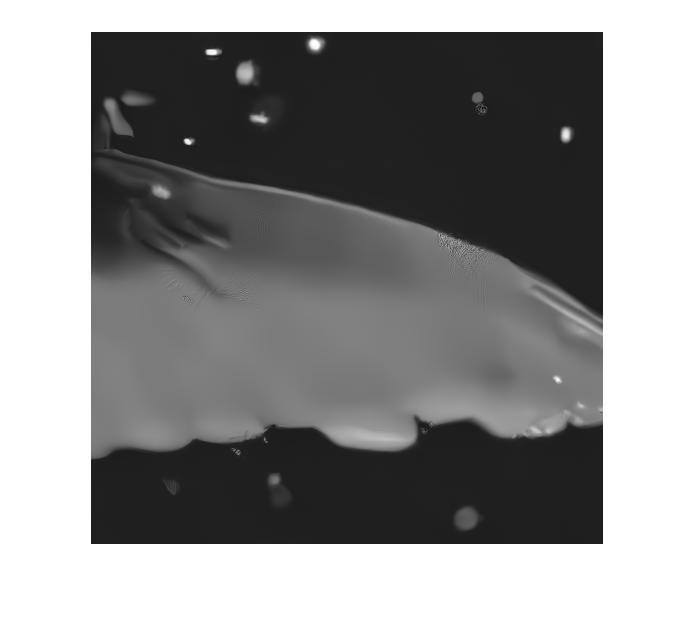

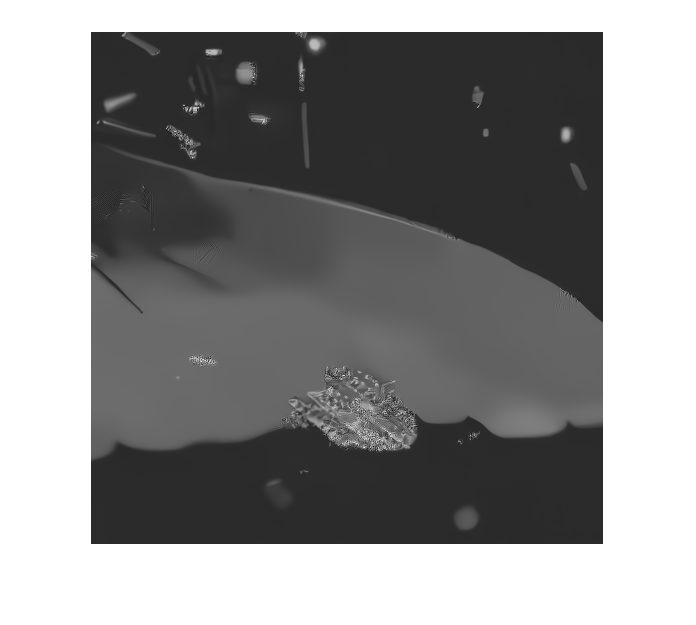

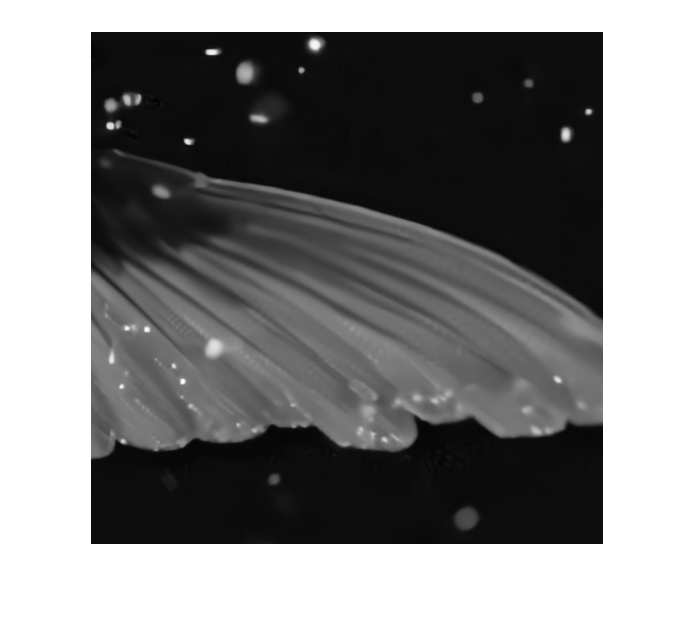

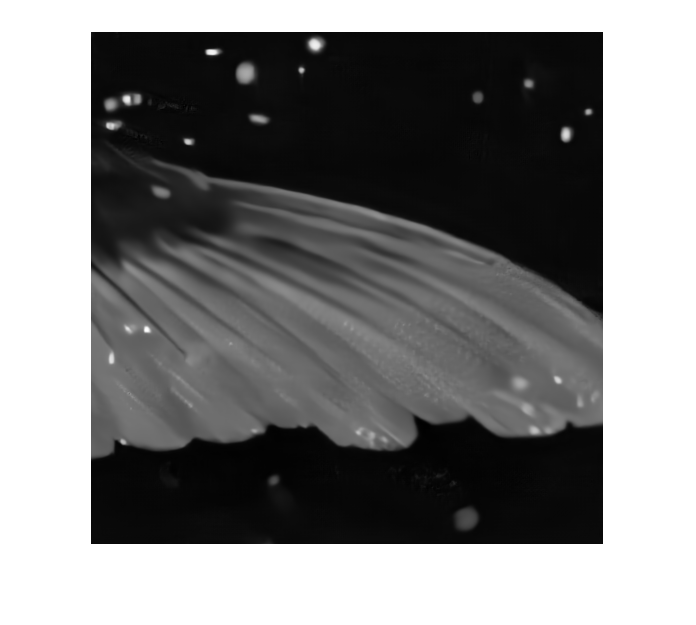

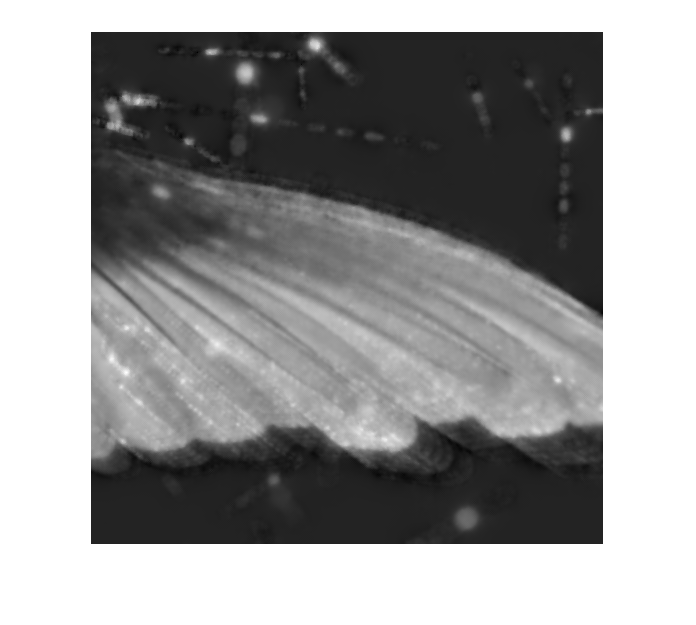

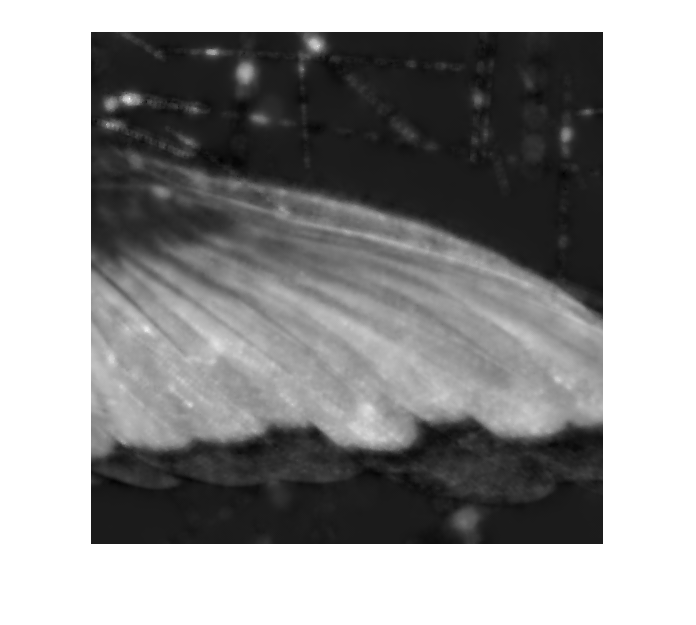


for k = 1:file_num
    filek = load([root_dir file_names{k}]);
    filek = filek.vdenoise;
    figure
    imshow(filek(:,:,img_idx),[]);    
    imwrite(uint8(255*filek(:,:,img_idx)), [save_dir file_names{k}(1:end-4) '_frame' num2str(img_idx) '.tif'])
end

## BIRNAT

root_dir = 'E:\project\CACTI\paper\figures\simu_experiment\exp1\mat\256\BIRNAT\'

root_dir = 'E:\project\CACTI\paper\figures\simu_experiment\exp1\mat\256\BIRNAT\'


% ---
% save_dir = 'E:\project\CACTI\paper\figures\simu_experiment\exp1\tif\256\ReadySteadyGo\'
% img_idx = 28
% % data_name = 'backward_ReadySteadyGo_25625_23.7894_0.8279.mat';
% data_name = 'backward_ReadySteadyGo_256_25_29.4992_0.9389.mat';

save_dir = 'E:\project\CACTI\paper\figures\simu_experiment\exp1\tif\256\football\'

save_dir = 'E:\project\CACTI\paper\figures\simu_experiment\exp1\tif\256\football\'

img_idx = 23

img_idx = 23

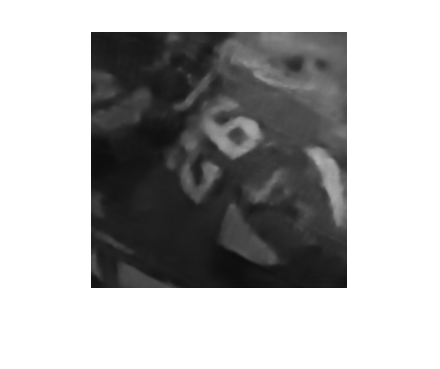

data_name = 'backward_football_25625_27.9115_0.9021.mat';
% data_name = 'backward_football_256_25_34.6667_0.9719.mat';

% ---

pic = load([root_dir data_name]);
pic = pic.pic;
Cr = 40/size(pic,1);

meas_idx = ceil(img_idx./Cr);
frame_idx = mod(img_idx, Cr);
framek = pic(meas_idx, frame_idx,:,:);
framek = squeeze(framek);
imshow(framek);    

imwrite(uint8(255*framek), [save_dir data_name(1:end-4) '_frame' num2str(img_idx) '.tif'])

## old version code



%% -----------------------------------------------------------------
% % ----- 256
% if scale==256
%     img_idx = 8;
%     
%     data_name10 = 'YachtRide_256.mat';
%     data_name11 = 'gaptv+fastdvdnet_YachtRide_256_Cr10_kmeas0_3.mat';
%     data_name12 = 'gaptv_YachtRide_256_Cr10_kmeas0_3.mat';
%     
%     data_name20 = 'YachtRide_256.mat';
%     data_name21 = 'gaptv+fastdvdnet_YachtRide_256_Cr20_kmeas0_1.mat';
%     data_name22 = 'gaptv_YachtRide_256_Cr20_kmeas0_1.mat';
% 
% end
% 
% if scale==512
%     img_idx = 13;
%     data_name10 = 'Jockey_512.mat';
%     data_name11 = 'gaptv+fastdvdnet_Jockey_512_Cr10_kmeas0_3.mat';
%     data_name12 = 'gaptv_Jockey_512_Cr10_kmeas0_3.mat';
%    
%     data_name20 = 'Jockey_512.mat';
%     data_name21 = 'gaptv+fastdvdnet_Jockey_512_Cr20_kmeas0_1.mat';
%     data_name22 = 'gaptv_Jockey_512_Cr20_kmeas0_1.mat';
% end
% 
% if scale==1024
%     img_idx = 24;
%     data_name10 = 'football_1024.mat';
%     data_name11 = 'gaptv_football_1024_Cr10_kmeas0_3.mat';
%     data_name12 = 'gaptv+fastdvdnet_football_1024_Cr10_kmeas0_3.mat';
%     
%     data_name20 = 'football_1024.mat';
%     data_name21 = 'gaptv_football_1024_Cr20_kmeas0_1.mat';
%     data_name22 = 'gaptv+fastdvdnet_football_1024_Cr20_kmeas0_1.mat';
% end
% 
% %% load & convert
% d10 = load([root_dir data_name10]);
% d10 = d10.orig;
% d11 = load([root_dir data_name11]);
% d11 = d11.vdenoise;
% d12 = load([root_dir data_name12]);
% d12 = d12.vdenoise;
% 
% d20 = load([root_dir data_name10]);
% d20 = d20.orig;
% d21 = load([root_dir data_name11]);
% d21 = d21.vdenoise;
% d22 = load([root_dir data_name12]);
% d22 = d22.vdenoise;
% 
% 
% % show
% figure
% imshow(d10(:,:,img_idx),[]);
% figure
% imshow(d11(:,:,img_idx),[]);
% figure
% imshow(d12(:,:,img_idx),[]);
% 
% figure
% imshow(d20(:,:,img_idx),[]);
% figure
% imshow(d21(:,:,img_idx),[]);
% figure
% imshow(d22(:,:,img_idx),[]);
% 
% 
% % save
% imwrite(d10(:,:,img_idx), [save_dir data_name10(1:end-4) '_frame' num2str(img_idx) '.tif'])
% imwrite(uint8(255*d11(:,:,img_idx)), [save_dir data_name11(1:end-4) '_frame' num2str(img_idx) '.tif'])
% imwrite(uint8(255*d12(:,:,img_idx)), [save_dir data_name12(1:end-4) '_frame' num2str(img_idx) '.tif'])
% 
% imwrite(d20(:,:,img_idx), [save_dir data_name20(1:end-4) '_frame' num2str(img_idx) '.tif'])
% imwrite(uint8(255*d21(:,:,img_idx)), [save_dir data_name21(1:end-4) '_frame' num2str(img_idx) '.tif'])
% imwrite(uint8(255*d22(:,:,img_idx)), [save_dir data_name22(1:end-4) '_frame' num2str(img_idx) '.tif'])

% for i = 1:img_num
% 	imwrite(orig(:,:,:,i), [save_dir data_name(1:end-4) '.tif'], 'WriteMode','append')
% end